m_out = double(out.simout(300:end));

m_in = 190*ones(size(m_out,1),1);

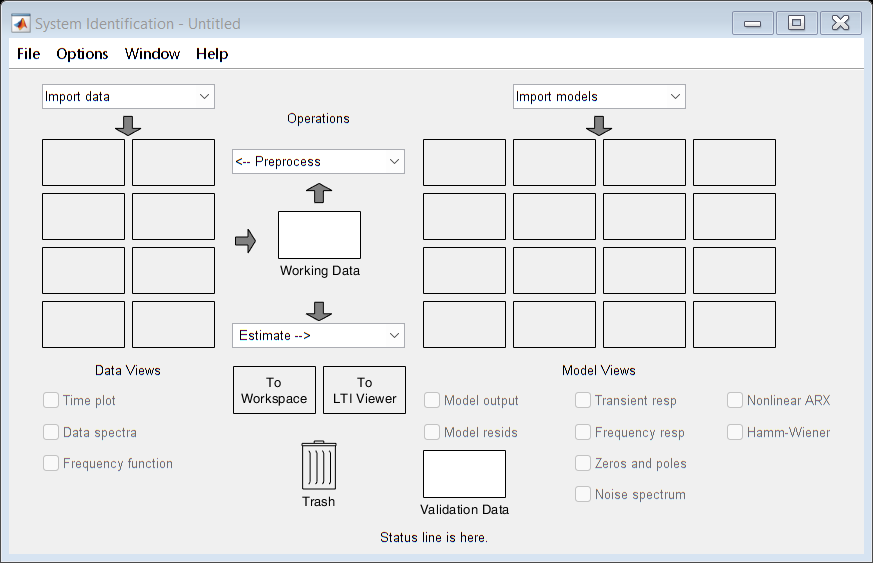

ident()

m_tf = tf(tf1)

m_tf =
 
  From input "u1" to output "y1":
            0.02517
  ---------------------------
  1 - 1.56 z^-1 + 0.5847 z^-2
 
Name: tf1
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


c_tf = tf(tf2)

c_tf =
 
  From input "u1" to output "y1":
          190.1
  ---------------------
  s^2 + 34.94 s + 184.3
 
Name: tf2
Continuous-time transfer function.
Model Properties


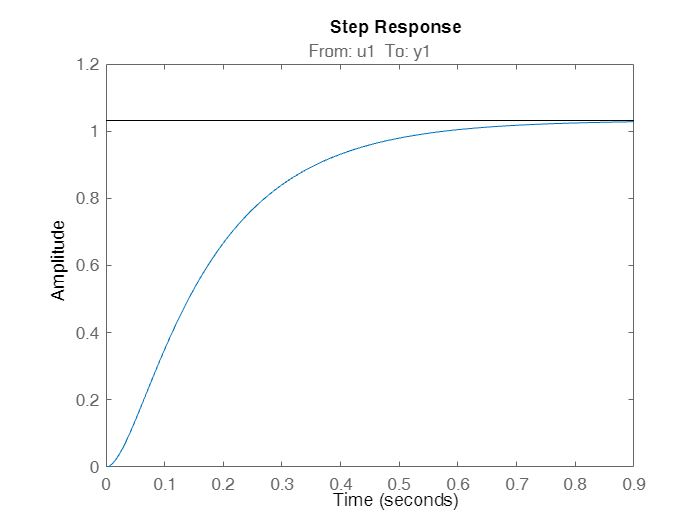

step(tf2)


sisotool(c_tf)